Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# One-dimensional tracking (Section 11.1)

Volker Ziemann, 211120

In this example we show the phase-space plot of a ring where a single sextupole provides the non-linearity that is defined by Equation 11.3. We follow particles with increasing initial values for 1024 iterations and plot a dot at their phase-space coordinate after every iteration.

We first define teh number of turns to follow and provide a selection of tunes `Q` to choose from and a slider to set the offset `dx`. Then we define the transfer matrix, which is just a rotation matrix with phase advance given by $2\pi Q$. 

clear all;
Nturn=1024;
Qstr="0.2526";             % select tune
Q=str2double(Qstr)

Q = 0.2526

dx=0       % misalignment

dx = 0

R=@(mu)[cos(mu),sin(mu);-sin(mu),cos(mu)];
RR=R(2*pi*Q);
clf

With the preliminaries defined, we set the sacle of the axes and loop over initial starting values` x0`.

hold on
axis([-1.2,1.2,-1.2,1.2]); 
title(['Q = ',num2str(Q,4),',   dx = ',num2str(dx,2)]);
for x0=0.05:0.05:2

For each starting value we allocate an array data to hold the phase-space coordinates after each iteration and set the start coordinate, before iterating `Nturn` times. In each iteration we apply Equation 11.3 and store the coordinate in data. If the coorsinate is larger than 3, we break the iteration.

  data=zeros(2,Nturn);
  x=[x0;0];               % start coordinates
  for n=1:Nturn
    x=RR*[x(1);x(2)-(x(1)-dx)^2];
    if (abs(x(1))>3) break; end
    data(:,n)=x;
  end

And finally we display the phase-space points as a black dot and give MATLAB a little time to update the display and annotate the axes.

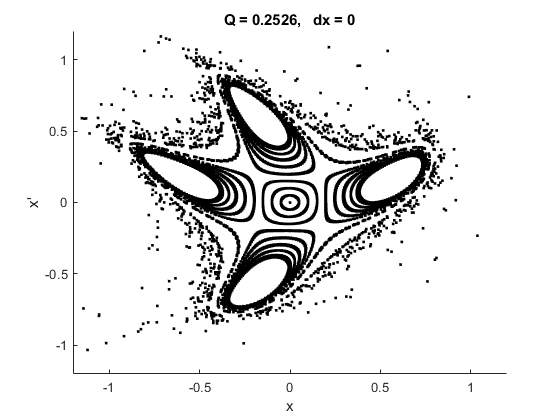

  plot(data(1,1:n),data(2,1:n),'k.')
  pause(0.001)
end
xlabel('x'); ylabel('x''')